clear; clc;

% --- Parameters ---
data_folder = '/Users/manoharpaturi/Desktop/EEE S2 Proj/TestCasesLibrary_Measurement/Forced oscillation/Case 1F';
dt = 40 / 1200; % Time step (s)
expected_gens = 29; % Expected number of generators
fixed_rank = 29; % Force 29 modes
reg_param = 1e-2; % Regularization parameter for DMD

% --- Load Data ---
try
    [Xraw, num_gens] = load_data(data_folder, dt);
    if num_gens ~= expected_gens
        error('Number of generators (%d) does not match expected (%d).', num_gens, expected_gens);
    end
    fprintf('Number of generators: %d\n', num_gens);
catch e
    error('Failed to load data: %s', e.message);
end

Raw data size for rotor_speeds.csv: 1201 rows, 29 columns
Loaded rotor_speeds.csv: 1201 rows, 29 columns
Raw data size for rotor_angles.csv: 1201 rows, 29 columns
Loaded rotor_angles.csv: 1201 rows, 29 columns
Final Xraw: 29 signals, 2402 time steps


Number of generators: 29



% --- Prepare DMD Inputs ---
Xraw = Xraw - mean(Xraw, 2); % Remove mean
X1 = Xraw(:, 1:end-1); % Snapshot t
X2 = Xraw(:, 2:end); % Snapshot t+1
t = (0:size(Xraw, 2)-1) * dt; % Time vector

% --- Rank Selection ---
try
    [U, S, V] = svd(X1, 'econ');
    singular_values = diag(S);
    r = min(fixed_rank, length(singular_values));
    if r < fixed_rank
        warning('Only %d singular values available; using rank %d.', length(singular_values), r);
    end
    fprintf('Selected rank for DMD: %d\n', r);
catch e
    error('SVD failed: %s', e.message);
end

Selected rank for DMD: 29



--- Extended DMD ---


Reconstruction Error: 2.454898e+09


Modes (29 total):


    frequency    damping_ratio      energy      amplitude    dominant_generator
    _________    _____________    __________    _________    __________________

           0              -1      2.3511e+07       4848.8            16        
           0              -1       1.041e+05       322.65            16        
           0               1      0.00083526     0.028901            13        
     0.13555         0.25447       0.0014544     0.038137            23        
     0.13555         0.25447       0.0014544     0.038137            23        
     0.24555       -0.010129      0.00017358     0.013175            23        
     0.24555       -0.010129      0.00017358     0.013175            23        
     0.42599       -0.019737      0.00012976     0.011391            13        
     0.42599       -0.019737 

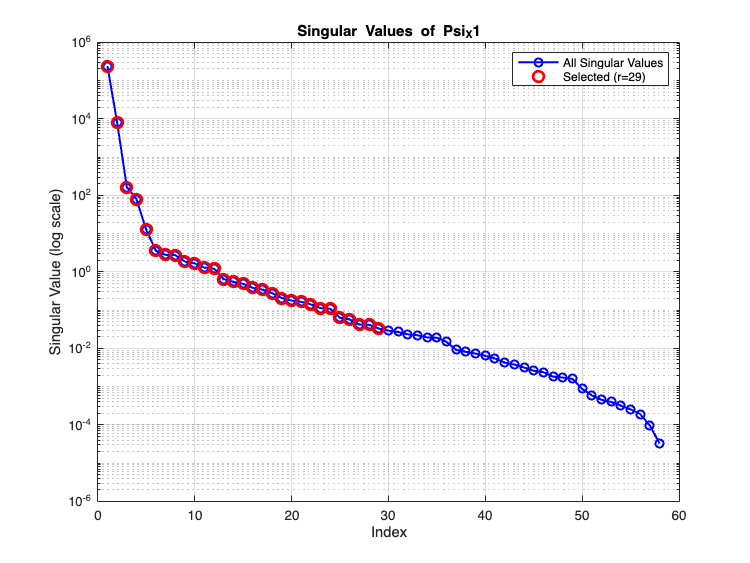

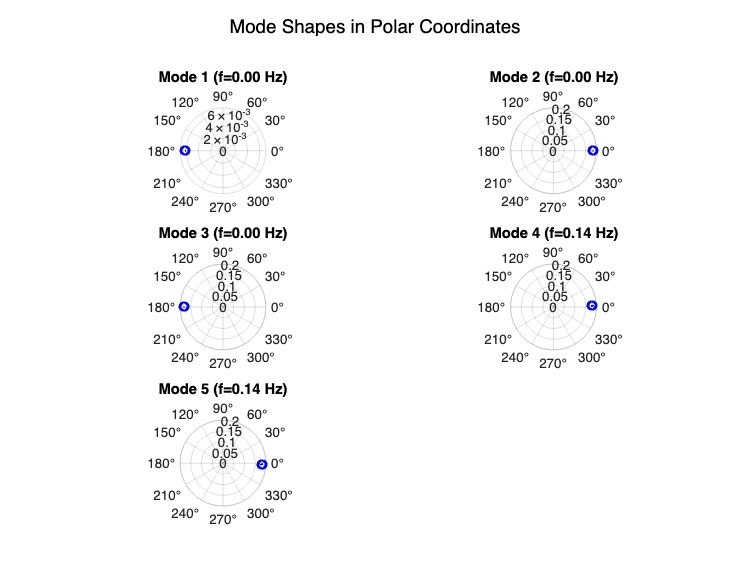

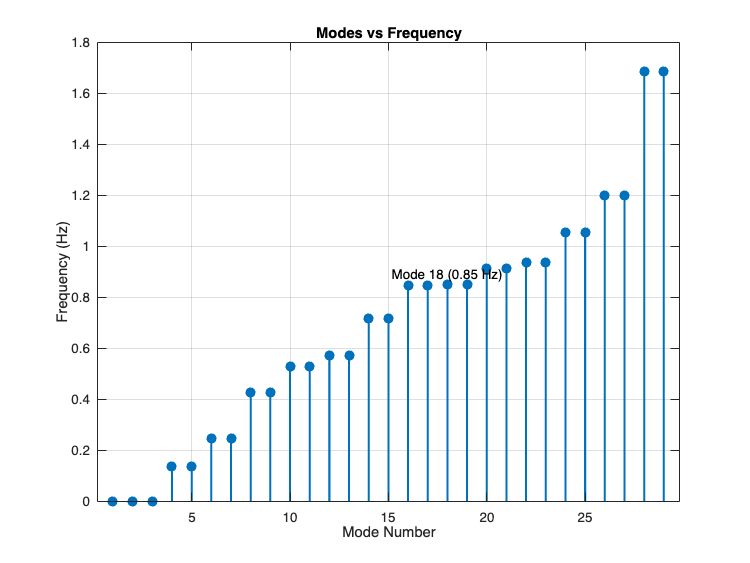


% --- Extended DMD ---
try
    % Define dictionary of observables (linear + quadratic terms)
    num_signals = size(X1, 1); % 58 signals (29 speeds + 29 angles)
    Psi_X1 = [X1; X1.^2]; % Augment with quadratic terms
    Psi_X2 = [X2; X2.^2]; % Same for X2
    % SVD of augmented data
    [U_psi, S_psi, V_psi] = svd(Psi_X1, 'econ');
    singular_values_psi = diag(S_psi);
    r_psi = min(fixed_rank, length(singular_values_psi));
    if r_psi < fixed_rank
        warning('Only %d singular values available for Psi_X1; using rank %d.', length(singular_values_psi), r_psi);
    end
    Ur_psi = U_psi(:, 1:r_psi); Sr_psi = S_psi(1:r_psi, 1:r_psi); Vr_psi = V_psi(:, 1:r_psi);
    % Compute Koopman operator
    Atilde_psi = Ur_psi' * Psi_X2 * Vr_psi / Sr_psi;
    Atilde_psi_reg = Atilde_psi + reg_param * eye(size(Atilde_psi));
    % Eigenvalue decomposition
    [Phi_psi_reg, Lambda_psi] = eig(Atilde_psi_reg);
    Phi_edmd = Psi_X2 * Vr_psi / Sr_psi * Phi_psi_reg; % Mode shapes
    lambda_edmd = diag(Lambda_psi); % Eigenvalues
    if length(lambda_edmd) > fixed_rank
        lambda_edmd = lambda_edmd(1:fixed_rank);
        Phi_edmd = Phi_edmd(:, 1:fixed_rank);
    end
    b_edmd = pinv(Phi_edmd) * Psi_X1(:, 1); % Mode amplitudes
    % Dimension checks
    assert(size(Phi_edmd, 2) == length(b_edmd), 'Extended DMD: Phi and b dimensions mismatch');
    assert(length(b_edmd) == length(lambda_edmd), 'Extended DMD: b and lambda dimensions mismatch');
    % Reconstruct data (project back to original space)
    X_recon_edmd = zeros(size(Xraw));
    for k = 1:length(t)
        Psi_k = [Xraw(:, k); Xraw(:, k).^2];
        X_recon_edmd(:, k) = real(Phi_edmd(1:num_signals, :) * (b_edmd .* lambda_edmd.^(k-1)));
    end
    error_edmd = norm(Xraw - X_recon_edmd, 'fro') / norm(Xraw, 'fro');
    % Analyze modes
    mode_props_edmd = analyze_modes(Phi_edmd(1:num_signals, :), lambda_edmd, ...
        abs(imag(log(lambda_edmd)/dt))/(2*pi), ...
        -real(log(lambda_edmd)/dt)./abs(log(lambda_edmd)/dt), b_edmd, num_gens);
catch e
    fprintf('Error in Extended DMD: %s\n', e.message);
    error_edmd = NaN;
    mode_props_edmd = [];
end

% --- Display Modes and Plots ---
if ~isnan(error_edmd) && ~isempty(mode_props_edmd) && height(mode_props_edmd) > 0
    fprintf('\n--- Extended DMD ---\n');
    fprintf('Reconstruction Error: %.6e\n', error_edmd);
    fprintf('Modes (%d total):\n', height(mode_props_edmd));
    
    % Compute dominant generators
    dominant_gen = zeros(height(mode_props_edmd), 1);
    for j = 1:height(mode_props_edmd)
        mode_shape = mode_props_edmd.mode_shape{j}(1:num_gens);
        participation = calc_participation(mode_shape, num_gens);
        [~, max_gen] = max(participation);
        dominant_gen(j) = max_gen;
    end
    mode_props_edmd.dominant_generator = dominant_gen;
    
    % Display table
    try
        disp(mode_props_edmd(:, {'frequency', 'damping_ratio', 'energy', 'amplitude', 'dominant_generator'}));
    catch e
        fprintf('Error displaying table: %s\n', e.message);
    end
    
    % --- Plotting ---
    % Singular Values Plot
    try
        figure;
        semilogy(singular_values_psi, 'bo-', 'LineWidth', 1.5);
        hold on;
        semilogy(singular_values_psi(1:r_psi), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
        title('Singular Values of Psi_X1', 'FontSize', 14);
        xlabel('Index', 'FontSize', 12);
        ylabel('Singular Value (log scale)', 'FontSize', 12);
        legend('All Singular Values', sprintf('Selected (r=%d)', r_psi));
        grid on;
        set(gca, 'FontSize', 10);
    catch e
        fprintf('Error in singular values plot: %s\n', e.message);
    end
    
    % Mode Shapes in Polar Coordinates (first few modes)
    try
        num_modes_to_plot = min(5, height(mode_props_edmd)); % Plot up to 5 modes
        figure;
        for j = 1:num_modes_to_plot
            subplot(ceil(num_modes_to_plot/2), 2, j);
            mode_shape = mode_props_edmd.mode_shape{j}(1:num_gens);
            theta = angle(mode_shape); % Phase in radians
            rho = abs(mode_shape); % Magnitude
            polarplot(theta, rho, 'bo-', 'LineWidth', 1.5);
            title(sprintf('Mode %d (f=%.2f Hz)', j, mode_props_edmd.frequency(j)), 'FontSize', 10);
            pax = gca;
            pax.ThetaAxisUnits = 'degrees';
            pax.FontSize = 10;
        end
        sgtitle('Mode Shapes in Polar Coordinates', 'FontSize', 14);
    catch e
        fprintf('Error in mode shapes plot: %s\n', e.message);
    end
    
    % Modes vs Frequency Plot
    try
        figure;
        mode_numbers = 1:height(mode_props_edmd);
        stem(mode_numbers, mode_props_edmd.frequency, 'filled', 'LineWidth', 1.5, 'MarkerSize', 6);
        title('Modes vs Frequency', 'FontSize', 14);
        xlabel('Mode Number', 'FontSize', 12);
        ylabel('Frequency (Hz)', 'FontSize', 12);
        grid on;
        % Label the mode closest to 0.86 Hz
        [~, idx_086] = min(abs(mode_props_edmd.frequency - 0.86));
        text(mode_numbers(idx_086), mode_props_edmd.frequency(idx_086)*1.05, ...
             sprintf('Mode %d (%.2f Hz)', idx_086, mode_props_edmd.frequency(idx_086)), ...
             'FontSize', 10, 'HorizontalAlignment', 'center');
        set(gca, 'FontSize', 10);
    catch e
        fprintf('Error in modes vs frequency plot: %s\n', e.message);
    end
else
    fprintf('\n--- Extended DMD ---\n');
    fprintf('Failed to compute modes.\n');
end


% --- Helper Functions ---

function [Xraw, num_gens] = load_data(data_folder, dt)
    file_names = {'rotor_speeds.csv', 'rotor_angles.csv'};
    Xraw = [];
    num_gens = 0;
    
    for i = 1:length(file_names)
        file_path = fullfile(data_folder, file_names{i});
        if exist(file_path, 'file')
            data = readmatrix(file_path, 'NumHeaderLines', 1);
            if size(data, 2) < 2
                warning('File %s has insufficient columns.', file_names{i});
                continue;
            end
            data = data(:, 2:end);
            fprintf('Raw data size for %s: %d rows, %d columns\n', file_names{i}, size(data, 1), size(data, 2));
            if contains(file_names{i}, 'rotor_speeds', 'IgnoreCase', true)
                num_gens = size(data, 2);
                mean_spd = mean(data(:));
                if mean_spd < 1
                    warning('Rotor speeds appear to be in per-unit (mean = %.4f). Converting to Hz assuming 60 Hz base.', mean_spd);
                    data = data * 60;
                end
            else
                max_val = max(abs(data(:)));
                if max_val > 0
                    data = data / max_val;
                else
                    data = zeros(size(data));
                end
            end
            Xraw = [Xraw; data];
            fprintf('Loaded %s: %d rows, %d columns\n', file_names{i}, size(data, 1), size(data, 2));
        else
            warning('File %s not found.', file_path);
        end
    end
    
    if isempty(Xraw)
        error('No data loaded.');
    end
    
    Xraw = Xraw';
    fprintf('Final Xraw: %d signals, %d time steps\n', size(Xraw, 1), size(Xraw, 2));
end

function mode_props = analyze_modes(Phi, lambda, freq_Hz, damping_ratio, b, num_gens)
    num_modes = length(lambda);
    mode_energy = abs(b).^2;
    amplitude = abs(b); % Amplitude is the magnitude of b
    
    mode_shapes = cell(num_modes, 1);
    for i = 1:num_modes
        mode_shapes{i} = Phi(:, i);
    end
    
    mode_props = table(...
        freq_Hz(:), damping_ratio(:), mode_energy(:), amplitude(:), mode_shapes, ...
        'VariableNames', {'frequency', 'damping_ratio', 'energy', 'amplitude', 'mode_shape'});
    
    mode_props = sortrows(mode_props, 'frequency');
end

function participation = calc_participation(mode_shape, num_gens)
    if length(mode_shape) < num_gens
        error('Mode shape length (%d) less than num_gens (%d).', length(mode_shape), num_gens);
    end
    mode = mode_shape(1:num_gens);
    norm_val = norm(mode);
    if norm_val > 1e-6
        normalized = mode / norm_val;
    else
        normalized = zeros(size(mode));
    end
    participation = abs(normalized).^2;
end